# Linear Regression

**Author**: Scott Campit

## Summary

This livescript is a tutorial to write up a linear regressor written from scratch. We will use the `carbig` dataset built into MATLAB to predict MPG based on all other numerical datasets that are not categoricals. First, we will build a linear regressor using gradient descent. Then we will use the normal equation to compute the regression coefficient. Finally, we'll use MATLAB's functions to train a model.

## Construct the regression dataset

Let X be attributes that are useful to predict MPG. The continuous values include acceleration, displacement, horsepower, and weight.

load carbig.mat
Y = MPG;
X = [Acceleration, Displacement, Horsepower, Weight];

% Normalize data using mean = 0 and standard deviation = 1
mu = nanmean(X);
sigma = nanstd(X);
X = (X - mu) ./ sigma

% Remove NaNs
Y(any(isnan(X), 2), :) = [];
X(any(isnan(X), 2), :) = [];
X(any(isnan(Y), 2), :) = [];
Y(any(isnan(Y), 2), :) = [];

### Split into training and test datasets

Next, we have to split the data into a training and test set. Let's use this `trainTestSplit` function:

trainingSize = 0.8;
randomState = 'default';
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X, Y, trainingSize, randomState);

## Initialize the regression coefficients and intercept to be small and random numbers

First, we need to initialize the regression coefficients to be some small, arbitrary value with the size of the number of predictors. The intercept needs to be the number of samples in the dataset by one column.

beta      = randn([size(Xtrain, 2), 1]) * 0.001;
intercept = randn([size(Xtrain, 1), 1]) * 0.001;

### Define necessary training functions

Included in this repository are some additional functions we need to run the linear regressor. Here are the necessary components: training phase (forward propagation), cost evaluation, and learning phase (backward propagation + gradient descent). 

## Train the linear regressor

The next bit of code utilized all of the functions above to train a linear regressor. This for loop can be packaged into another function, but it is explicitly written below.

% Intialize some hyperparameters
epochs = 1000;
alpha = 0.001;

% Linear regression using Gradient Descent
for i = 1:epochs
    yhat = forwardProp(Xtrain, beta, intercept);
    J(i) = costEvaluation(Ytrain, yhat);
    [beta, intercept] = backProp(Xtrain, Ytrain, yhat, ...
                                 alpha, beta, intercept);
end

### The MSE curve

Let's see how the error or cost reduces with each iteration:

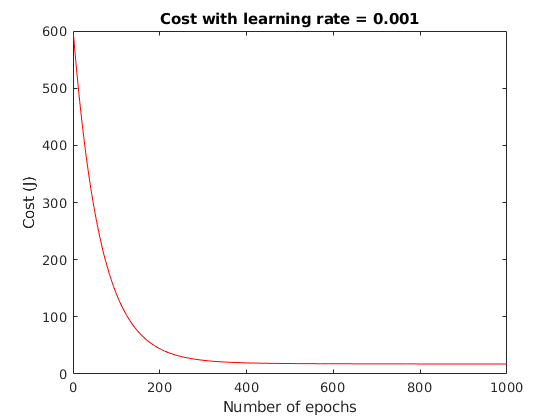

% Cost curve
figure; plot(1:epochs, J, 'color', 'r');
title('Cost with learning rate = 0.001')
xlabel('Number of epochs'); ylabel('Cost (J)')

After 400 epochs, the model MSE plateaus. So the idea number of epochs would be around 400 to reduce the risk of overfitting.

## Evaluating the model

To evaluate the model, let's look at the hold out pearson correlation coefficient, then perform cross validation.

### Hold out metrics

ypred_val = sum(Xtest .* beta', 2);

ypred_val =   -14.6451
  -10.9736
   -8.9207
    4.0185
    0.5170
   -2.0357
  -12.9002
    4.5891
    8.2980
    8.5560


mse = 1 / size(Ytest, 1) * sum((ypred_val - Ytest) .^ 2);

mse = 617.4621

[pears, pval] = corr(ypred_val, Ytest);

pears = 0.8267

pval = 6.3958e-21

### Cross validation metrics

We'll use the following cross validation function to evaluate the model

kfold = 5;
summary = crossValidate_lm(X, Y, kfold)

summary = struct with fields:
     name: "Linear regressor summary"
      mse: 579.0678
     beta: [4×1 double]
    pears: 0.8267
     pval: 6.3948e-21


## Interpreting the linear regressor on the cars dataset

summary.beta

ans =     0.0677
   -2.1076
   -1.9040
   -2.6392


To wrap things up, the pearson correlation coefficient is 0.82 and the p-value of the pearson correlation coefficient w.r.t a normal distribution is 6.39E-21. This means that the model captures the relationship betwen MPG and the acceleration, displacement, horsepower, and weight for each car with a strong positive correlation. 

By examining the beta cofficients, acceleration is positively correlated with MPG, while displacement, horsepower, and weight are negatively correlated with MPG. Thus, if you want to maximize the MPG, you would want a car that can accelerate quickly, but has low horsepower and weight. 

## Using the normal equation

Of course, there's another way to compute the regression coefficients by using the **normal equation**:


$$\beta^ˆ ={\left(X^T X\right)}^{-1} X^T y$$


% Use normal equation
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X, Y, trainingSize, randomState);
beta_normal = inv(Xtrain' * Xtrain) * (Xtrain' * Ytrain)

beta_normal =    -1.1483
   -1.2491
   -4.6071
   -1.6670


% Evaluate normal equation
ypred_val = sum(Xtest .* beta_normal', 2)

ypred_val =   -15.7287
  -11.2534
   -8.8429
    3.5801
    1.8727
   -1.2464
  -12.1927
    4.2825
    7.1856
    7.4228


mse = 1 / size(Ytest, 1) * sum((ypred_val - Ytest) .^ 2)

mse = 618.2125

[pears, pval] = corr(ypred_val, Ytest)

pears = 0.8230

pval = 1.3485e-20

As you can see, we get very similar performances using both models.

## Using `fitlm` from MATLAB

Now that we have ran through an algorithmic understanding of linear regression, and the math required to solve the regression coefficients from a learning and analytic perspective, let's see how we can fit a linear regressor using MATLAB's functions, which will most likely be the way you use these tools. However, hopefully from this exercise, you have a better understanding on how a regressor works under the hood, as we will tweak these parameters in our next lecture. 

[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X, Y, trainingSize, randomState);
mdl = fitlm(Xtrain, Ytrain)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       23.158    0.23507      98.514    6.521e-235
    x1             -0.084649    0.37895    -0.22338       0.82339
    x2              -0.84028    0.78274     -1.0735       0.28388
    x3               -1.6389     0.6944     -2.3602      0.018891
    x4               -4.3482    0.75933     -5.7264     2.437e-08


Number of observations: 313, Error degrees of freedom: 308
Root Mean Squared Error: 4.15
R-squared: 0.714,  Adjusted R-Squared: 0.71
F-statistic vs. constant model: 192, p-value = 2.15e-82

The estimate is the regression coefficient, the standard error is the measure of the standard deviation associated with each regression coefficient, the T score is where the regression coefficient lies in a normal distribution and how far it is from 0, and the two-tailed p-value tests the hypothesis that the coefficient is equal to 0 or not.

This summary suggests that horsepower and weight are significant contributors to predicting MPG. Further, all features from this algorithm show that there is actually a negative relationship between each feature and MPG. This does differ from our previous analysis, and does suggest that acceleration is not a great indicator of MPG, which is reflected in the p-value

Let's now use the model for making a prediction and evaluate the prediction.

ypred = predict(mdl, Xtest)

ypred =     9.9183
   13.7473
   16.0769
   27.3729
   24.9239
   20.5605
    9.8072
   27.8233
   31.9317
   32.6062


mse = 1 / size(Ytest, 1) * sum((ypred - Ytest) .^ 2)

mse = 21.4029

[pears, pval] = corr(ypred, Ytest)

pears = 0.8318

pval = 2.2220e-21

As you can see, the built-in function does outperform our solutions, most likely to some additional optimization steps MATLAB performs under the hood, or due to random chance. However, both methods perform similarly.